# Partial Differential Equations

Partial differential equation is a class of differential equations involving more than one independent variable. In this chapter, we consider a general second-order PDE in two independent variables $x$ and $y$, which is written as


$$A\left(x,y\right)\frac{\partial^2 u}{{\partial x}^2 }+B\left(x,y\right)\frac{\partial^2 u}{\partial x\partial y}+C\left(x,y\right)\frac{\partial^2 u}{{\partial y}^2 }=f\left(x,y,u,\frac{\partial u}{\partial x},\frac{\partial u}{\partial y}\right)$$


for $x_0 \le x\le x_f$ and $y_0 \le y\le y_f$

with the boundary conditions given by 


$$u\left(x_0 ,y\right)=b_{\textrm{x0}} \left(y\right)$$



$$u\left(x_f ,y\right)=b_{\textrm{xf}} \left(y\right)$$



$$u\left(x,y_0 \right)=b_{\textrm{y0}} \left(x\right)$$



$$u\left(x,y_f \right)=b_{\textrm{yf}} \left(x\right)$$


These PDEs can be classified into three groups:

Elliptic PDE: if $B^2 -4\textrm{AC}<0$

Parabolic PDE: if $B^2 -4\textrm{AC}=0$

Hyperbolic PDE: if $B^2 -4\textrm{AC}>0$

## Parabolic PDE

In this livescript, we consider the one-dimensional heat equation written as


$$A\frac{\partial^2 u\left(x,y\right)}{{\partial x}^2 }=\frac{\partial u\left(x,t\right)}{\partial t}$$


for $0\le x\le x_f$ and $0\le t\le T$

with the boundary conditions given by 


$$u\left(0,t\right)=b_0 \left(t\right)$$



$$u\left(x_f ,t\right)=b_{\textrm{xf}} \left(t\right)$$


with the initial condition


$$u\left(x,0\right)=i_0 \left(x\right)$$


### Explicit Forward Euler Method

We apply the finite difference method to the PDE and replace the second derivative by the three-point central difference approximation and the first partial derivative with the forward difference approximation.


$$A\frac{u_{i+1}^k -2u_i^k +u_{i-1}^k }{{\Delta x}^2 }=\frac{u_i^{k+1} -u_i^k }{\Delta t}$$
 

This can be cast into the following algorithm, called the explicit forward Euler method, which is solved iteratively. This is written as

$u_i^{k+1} =r\left(u_{i+1}^k +u_{i-1}^k \right)+\left(1-2r\right)u_i^k$                    (9.2.3)

where $r=A\frac{\Delta t}{{\Delta x}^2 }$ and $i=1,2,\ldotp \ldotp \ldotp ,M-1$

Here, the spatial domain $\left\lbrack 0,x_f \right\rbrack$ is divided into $M$ sections, each of length $\Delta x=\frac{x_f }{M}$, and the time domain $\left\lbrack 0,T\right\rbrack$ is divided into $N$ segments, each of duration $\Delta t=\frac{T}{N}$. To find the stability of the algorithm, we substitute a trial solution

$u_i^k =\lambda_k e^{\textrm{ji}\frac{\pi }{P}}$                (9.2.4)

where $P$ is any nonzero integer, into Eq. 9.2.3, to get


$$\lambda =r\left(e^{j\frac{\pi }{P}} +e^{-j\frac{\pi }{P}} \right)+\left(1-2r\right)=1-2r\left(1-\cos \left(\frac{\pi }{P}\right)\right)$$


Since we must have $\left|\lambda \right|\le 1$ for nondivergence, the stability condition turns out to be


$$r=A\frac{\Delta t}{{\Delta x}^2 }\le \frac{1}{2}$$


This implies that the spatial interval is proportional to the time step, and decreasing the spatial interval would result to decreasing time step, which leads to increasing computational time. 

### Implicit Backward Euler Method

We apply the finite difference method to the PDE and replace the second derivative by the three-point central difference approximation and the first partial derivative with the backward difference approximation.


$$A\frac{u_{i+1}^k -2u_i^k +u_{i-1}^k }{{\Delta x}^2 }=\frac{u_i^k -u_i^{k-1} }{\Delta t}$$
 

This can be cast into the following algorithm, called the implicit backward Euler method. 

#### Dirichlet boundary condition

For the case of a Dirichlet type of boundary condition (function value fixed), the above equation is written as

${-\textrm{ru}}_{i-1}^k +\left(1-2r\right)u_i^k -ru_{i+1}^k =u_i^{k-1}$                    (9.2.3)

where $r=A\frac{\Delta t}{{\Delta x}^2 }$ and $i=1,2,\ldotp \ldotp \ldotp ,M-1$

Here, the spatial domain $\left\lbrack 0,x_f \right\rbrack$ is divided into $M$ sections, each of length $\Delta x=\frac{x_f }{M}$, and the time domain $\left\lbrack 0,T\right\rbrack$ is divided into $N$ segments, each of duration $\Delta t=\frac{T}{N}$. This is solved simultaneously, so that

$\left\lbrack \begin{array}{cccccc}
1+2r & -r & 0 & \cdots  & 0 & 0\\
-r & 1+2r & -r & \cdots  & 0 & 0\\
0 & -r & 1+2r & \cdots  & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & \cdots  & 1+2r & -r\\
0 & 0 & 0 & \cdots  & -r & 1+2r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1^k \\
u_2^k \\
u_3^k \\
\vdots \\
u_{M-2}^k \\
u_{M-1}^k 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u_1^k +ru_0^k \\
u_2^{k-1} \\
u_3^{k-1} \\
\vdots \\
u_{M-2}^{k-1} \\
u_{M-1}^{k-1} +ru_M^k 
\end{array}\right\rbrack$                  (9.2.9)

where $u_0^k$ and $u_M^k$ at both end points are given from the Dirichlet type of boundary condition.

#### Neumann boundary condition

For the case of a Nuemann type of boundary condition (derivative fixed), 


$$\frac{u_1^k -u_{-1}^k }{2\Delta x}=b_0^{\prime } \left(k\right)$$


the above difference equation is rewritten as

${-\textrm{ru}}_{-1}^k +\left(1+2r\right)u_0^k -ru_1^k =u_0^{k-1}$                        (9.2.8)

to get

$\left(1+2r\right)u_0^k -2ru_1^k =u_0^{k-1} -2rb_0^{\prime } \left(k\right)\Delta x$. We then have 

$\left\lbrack \begin{array}{cccccc}
1+2r & -r & 0 & \cdots  & 0 & 0\\
-r & 1+2r & -r & \cdots  & 0 & 0\\
0 & -r & 1+2r & \cdots  & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & \cdots  & 1+2r & -r\\
0 & 0 & 0 & \cdots  & -r & 1+2r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_0^k \\
u_1^k \\
u_2^k \\
\vdots \\
u_{M-2}^k \\
u_{M-1}^k 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u_0^{k-1} -2rb_0^{\prime } \left(k\right)\Delta x\\
u_1^{k-1} \\
u_2^{k-1} \\
\vdots \\
u_{M-2}^{k-1} \\
u_{M-1}^{k-1} +ru_M^k 
\end{array}\right\rbrack$                (9.2.13)

The unconditional stability of Eq 9.2.9 and Eq. 9.2.13 are really nice in the sense that they can be solved very efficiently by exploiting their tridiagonal structures and are guaranteed to be stable owing to their diagonal dominancy. The unconditional stability of Eq. 9.2.9 can be shown by substituting Eq. 9.2.4 into Eq. 9.2.8


$$-re^{-j\frac{\pi }{P}} +\left(1+2r\right)-re^{j\frac{\pi }{P}} =\frac{1}{\lambda }$$


where 


$$\lambda =\frac{1}{1+2r\left(1-\cos \left(\frac{\pi }{P}\right)\right)},\left|\lambda \right|\le 1$$


### Crank-Nicholson Method

We can improve the implicit backward Euler method further. We take the difference approximation of both sides at the same time point, i.e., the midpoint between $k+1$ and $k$. This then gives us


$$\frac{A}{2}\left(\frac{u_{i+1}^{k+1} -2u_i^{k+1} +u_{i-1}^{k+1} }{{\Delta x}^2 }+\frac{u_{i+1}^k -2u_i^k +u_{i-1}^k }{{\Delta x}^2 }\right)=\frac{u_i^{k+1} -u_i^k }{\Delta t}$$


which leads to the so-called Crank-Nicholson method

${\textrm{ru}}_{i+1}^{k+1} +2\left(1+r\right)u_i^{k+1} -ru_{i-1}^{k+1} ={\textrm{ru}}_{i+1}^k +2\left(1-r\right)u_i^k +ru_{i-1}^k$            (9.2.16)

where 

$r=A\frac{\Delta t}{{\Delta x}^2 }$.

With the Dirichlet/Neumann type of boundary condition on $x_0$ and $x_M$, respectively, this can be written into the following tridiagonal system of equations


$$\left\lbrack \begin{array}{cccccc}
2\left(1+r\right) & -r & 0 & \cdots  & 0 & 0\\
-r & 2\left(1+r\right) & -r & \cdots  & 0 & 0\\
0 & -r & 2\left(1+r\right) & \cdots  & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & \cdots  & 2\left(1+r\right) & -r\\
0 & 0 & 0 & \cdots  & -r & 2\left(1+r\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1^{k+1} \\
u_2^{k+1} \\
u_3^{k+1} \\
\vdots \\
u_{M-2}^{k+1} \\
u_{M-1}^{k+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
2\left(1-r\right) & -r & 0 & \cdots  & 0 & 0\\
-r & 2\left(1-r\right) & -r & \cdots  & 0 & 0\\
0 & -r & 2\left(1-r\right) & \cdots  & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & \cdots  & 2\left(1-r\right) & -r\\
0 & 0 & 0 & \cdots  & -r & 2\left(1-r\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1^k \\
u_2^k \\
u_3^k \\
\vdots \\
u_{M-2}^k \\
u_{M-1}^k 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
r\left(u_0^{k+1} +u_0^k \right)\\
0\\
0\\
\vdots \\
0\\
2r\left(b_M^{\prime } \left(k+1\right)+b_M^{\prime } \left(k\right)\right)
\end{array}\right\rbrack$$


This system of equations can also be solved very efficiently, and its unconditional stability can be shown by subtituting Eq. 9.2.4 into Eq. 9.2.16


$$2\lambda \left(1+r\left(1-\cos \left(\frac{\pi }{P}\right)\right)\right)=2\left(1-r\left(1-\cos \left(\frac{\pi }{P}\right)\right)\right)$$


where


$$\lambda =\frac{1-r\left(1-\cos \left(\frac{\pi }{P}\right)\right)}{1+r\left(1-\cos \left(\frac{\pi }{P}\right)\right)},\left|\lambda \right|\le 1$$


## Example 9.2. Heat Flow Equation

Consider the parabolic PDE


$$\frac{\partial^2 u\left(x,y\right)}{{\partial x}^2 }=\frac{\partial u\left(x,t\right)}{\partial t}$$


for $0\le x\le 1$ and $0\le t\le 0\ldotp 1$ with the boundary conditions


$$u\left(0,t\right)=0$$



$$u\left(1,t\right)=0$$



$$u\left(x,0\right)=\sin \left(\pi x\right)$$


Solve the one-dimensional heat equation

clear
%solve_heat
a = 1; %the parameter of (E9.2.1)
it0 = inline('sin(pi*x)','x'); %initial condition
bx0 = inline('0'); bxf = inline('0'); %boundary condition
xf = 1; M = 20; T = 0.1; N = 100; %r = 0.625
%analytical solution
uo = inline('sin(pi*x)*exp(-pi*pi*t)','x','t');
[u1,x,t] = heat_exp(a,xf,T,it0,bx0,bxf,M,N);

r = 0.4000

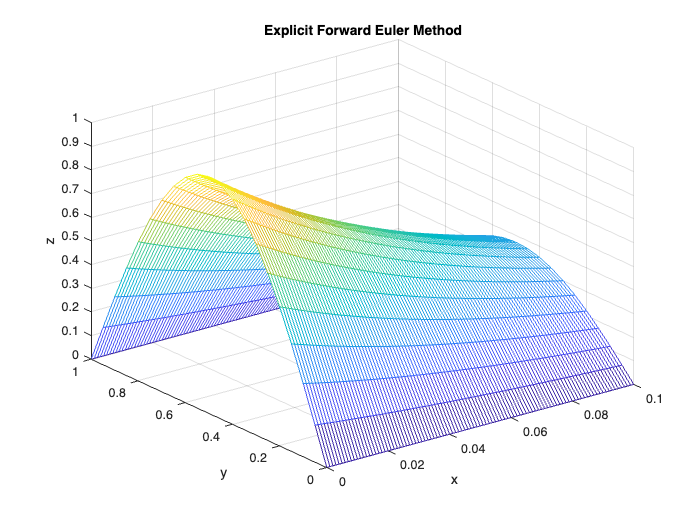

figure(1), clf, mesh(t,x,u1), title('Explicit Forward Euler Method')
xlabel('t'), ylabel('y'), zlabel('z')

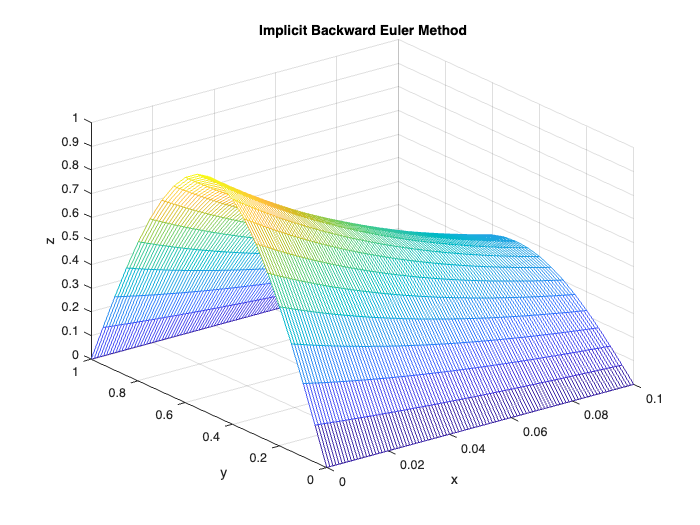

[u2,x,t] = heat_imp(a,xf,T,it0,bx0,bxf,M,N); %converge unconditionally
figure(2), clf, mesh(t,x,u2), title('Implicit Backward Euler Method')
xlabel('t'), ylabel('y'), zlabel('z')

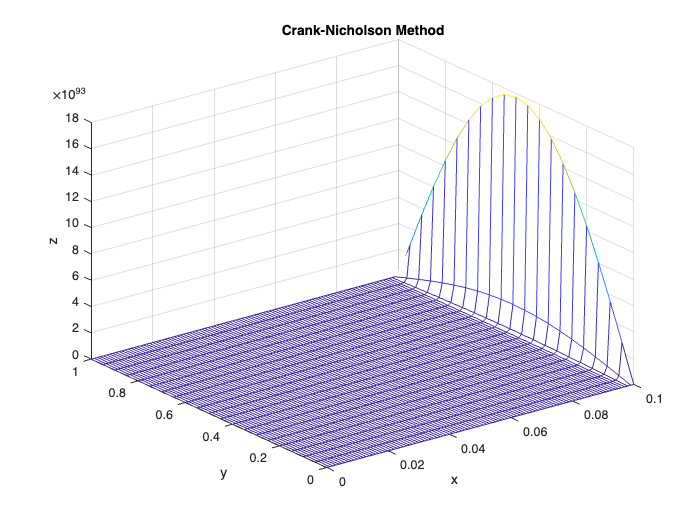

[u3,x,t] = heat_CN(a,xf,T,it0,bx0,bxf,M,N); %converge unconditionally
figure(3), clf, mesh(t,x,u3), title('Crank-Nicholson Method')
xlabel('t'), ylabel('y'), zlabel('z')

% axis([0 0.1 0 1 0 1])
MN = M*N;
Uo = uo(x,t); aUo = abs(Uo)+eps; %values of true analytical solution
%How far from the analytical solution?
err1 = norm((u1-Uo)./aUo)/MN

err1 = 0.0013

err2 = norm((u2-Uo)./aUo)/MN

err2 = 0.0013

err3 = norm((u3-Uo)./aUo)/MN

err3 = 1.0438e+92

### Explicit Forward Euler Method

function [u,x,t] = heat_exp(a,xf,T,it0,bx0,bxf,M,N)
    %solve a u_xx = u_t for 0 <= x <= xf, 0 <= t <= T
    % Initial Condition: u(x,0) = it0(x)
    % Boundary Condition: u(0,t) = bx0(t), u(xf,t) = bxf(t)
    % M = # of subintervals along x axis
    % N = # of subintervals along t axis
    dx = xf/M; x = [0:M]'*dx;
    dt = T/N; t = [0:N]*dt;
    for i = 1:M + 1, u(i,1) = it0(x(i)); end
    for n = 1:N + 1, u([1 M + 1],n) = [bx0(t(n)); bxf(t(n))]; end
    r = a*dt/dx/dx, r1 = 1 - 2*r;
    for k = 1:N
        for i = 2:M
            u(i,k+1) = r*(u(i + 1,k) + u(i-1,k)) + r1*u(i,k); %Eq.(9.2.3)
        end
    end
end

### Implicit Backward Euler Method

function [u,x,t] = heat_imp(a,xf,T,it0,bx0,bxf,M,N)
    %solve a u_xx = u_t for 0 <= x <= xf, 0 <= t <= T
    % Initial Condition: u(x,0) = it0(x)
    % Boundary Condition: u(0,t) = bx0(t), u(xf,t) = bxf(t)
    % M = # of subintervals along x axis
    % N = # of subintervals along t axis
    dx = xf/M; x = [0:M]'*dx;
    dt = T/N; t = [0:N]*dt;
    for i = 1:M + 1, u(i,1) = it0(x(i)); end
    for n = 1:N + 1, u([1 M + 1],n) = [bx0(t(n)); bxf(t(n))]; end
    r = a*dt/dx/dx; r2 = 1 + 2*r;
    for i = 1:M - 1
        A(i,i) = r2; %Eq.(9.2.9)
        if i > 1, A(i - 1,i) = -r; A(i,i - 1) = -r; end
    end
    for k = 2:N + 1
        b = [r*u(1,k); zeros(M - 3,1); r*u(M + 1,k)] + u(2:M,k - 1); %Eq.(9.2.9)
        u(2:M,k) = tridiagonal_matrix(A,b);
    end
end

### Crank-Nicholson Method

function [u,x,t] = heat_CN(a,xf,T,it0,bx0,bxf,M,N)
    %solve a u_xx = u_t for 0 <= x <= xf, 0 <= t <= T
    % Initial Condition: u(x,0) = it0(x)
    % Boundary Condition: u(0,t) = bx0(t), u(xf,t) = bxf(t)
    % M = # of subintervals along x axis
    % N = # of subintervals along t axis
    dx = xf/M; x = [0:M]'*dx;
    dt = T/N; t = [0:N]*dt;
    for i = 1:M + 1, u(i,1) = it0(x(i)); end
    for n = 1:N + 1, u([1 M + 1],n) = [bx0(t(n)); bxf(t(n))]; end
    r = a*dt/dx/dx;
    r1 = 2*(1 - r); r2 = 2*(1 + r);
    for i = 1:M - 1
        A(i,i) = r1; %Eq.(9.2.17)
        if i > 1, A(i - 1,i) = -r; A(i,i - 1) = -r; end
    end
    for k = 2:N + 1
        b = [r*u(1,k); zeros(M - 3,1); r*u(M + 1,k)] ...
        + r*(u(1:M - 1,k - 1) + u(3:M + 1,k - 1)) + r2*u(2:M,k - 1);
        u(2:M,k) = tridiagonal_matrix(A,b); %Eq.(9.2.17)
    end
end